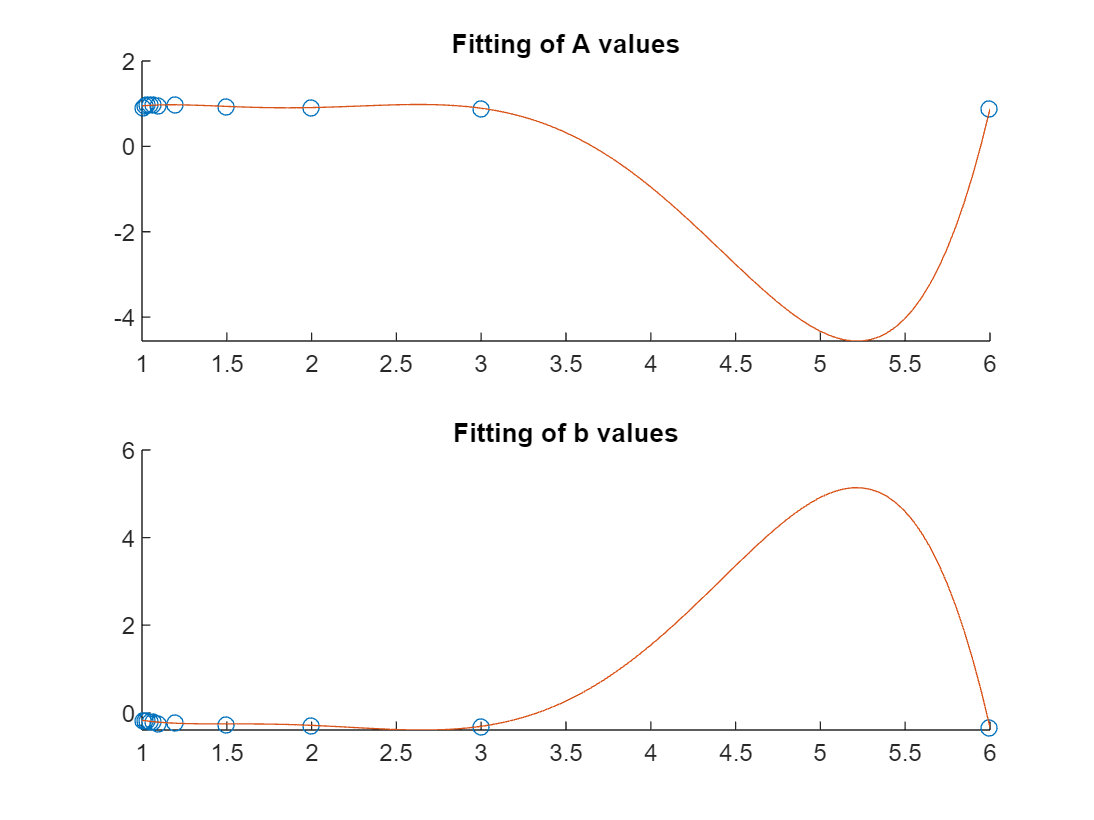

clf;
clear Afit bfit Ay by;
Dd = [6, 3, 2, 1.5, 1.2, 1.1, 1.07, 1.05, 1.03, 1.02, 1.01];
A = [0.87868, 0.89334, 0.90879, 0.93836, 0.97098, 0.95120, ...
    0.97527, 0.98137, 0.98061, 0.96048, 0.91938];
b = [-0.33243, -0.30860, -0.28598, -0.25759, -0.21796, -0.23757, ...
    -0.20958, -0.19653, -0.18381, -0.17711, -0.17032];

orderA = 5;
orderb = 5;
xl = 6;

Afit = polyfit(Dd, A, orderA);
bfit = polyfit(Dd, b, orderb);
testx = linspace(6, 1, 100);

figure(1);
subplot(2,1,1)
title('Fitting of A values')
hold on 
scatter(Dd, A)
Ay = polyval(Afit, testx);
plot(testx, Ay);
xlim([1,xl]);
hold off

subplot(2,1,2)
title('Fitting of b values')
hold on
scatter(Dd, b)
by = polyval(bfit, testx);
plot(testx, by);
xlim([1,xl]);
hold off